Was not used

fig = open ("AngleCallibration.fig")

fig =   Figure (2: Figure) with properties:

      Number: 2
        Name: 'Figure'
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


a = get (gca, 'Children');
x = get (a,'XData');
y = get(a,'YData');

xdata = cell2mat(x);
ydata = cell2mat(y);

data = [xdata; ydata];

tiltAngle = data(1,:);
panAngle = data(2,:);
tiltPos = data (3,:);
panPos = data (4,:);

% calibrationData = [panAngle;panPostiltAngle;tiltPos]'

calibrationData =     0.7854         0    4.1888         0
    1.9548    1.0000    2.0246    1.0000
    1.3614    0.5000    3.4907    0.5000
    0.7156    0.1000    4.0143    0.1000
    0.9599    0.2000    3.8397    0.2000
    1.0472    0.3000    3.6652    0.3000
    1.2217    0.4000    3.5779    0.4000
    1.3090    0.5000    3.3161    0.5000
    1.5359    0.6000    3.4034    0.6000
    1.6232    0.7000    3.1416    0.7000


load('rc_calibration_data.mat') % loading calibration data

panAngle = calibrationData(:,1);
panPos = calibrationData(:,2);
tiltAngle = calibrationData(:,3);
tiltPos = calibrationData(:,4);

% shifting the data to center it on 0 rad
tiltAngle_shifted = tiltAngle - (max(tiltAngle)+min(tiltAngle))/2;
panAngle_shifted = panAngle - (max(panAngle)+min(panAngle))/2;


fitting a curve (first order polynomial line) to match the data 

fit_pan = fit(panAngle_shifted,panPos,'poly1')

fit_pan =      Linear model Poly1:
     fit_pan(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.7265  (0.6787, 0.7742)
       p2 =      0.4839  (0.4635, 0.5043)

fit_tilt = fit(tiltAngle_shifted,tiltPos,'poly1')

fit_tilt =      Linear model Poly1:
     fit_tilt(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.6756  (-0.7092, -0.642)
       p2 =      0.4814  (0.4659, 0.4969)

save fitted curve

save fit_pan fit_pan
save fit_tilt fit_tilt

find range of movement

pan_movement = max(panAngle)-min(panAngle)

pan_movement = 1.3963

tilt_movement = max(tiltAngle)-min(tiltAngle)

tilt_movement = 1.4835

plotting the tilt vs command angle 

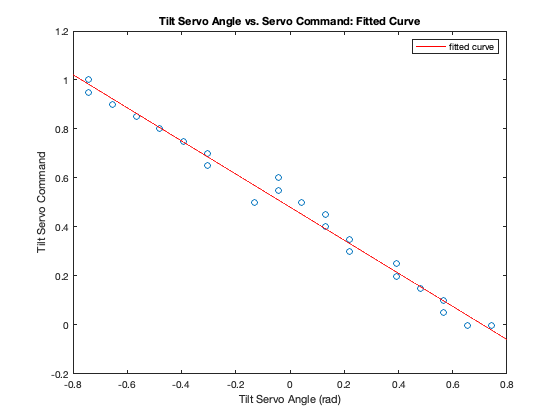

figure()
plot(tiltAngle_shifted,tiltPos,"o")
hold on;
plot(fit_tilt)
xlabel('Tilt Servo Angle (rad)')
ylabel('Tilt Servo Command')
title('Tilt Servo Angle vs. Servo Command: Fitted Curve')

plotting the pan vs command angle 

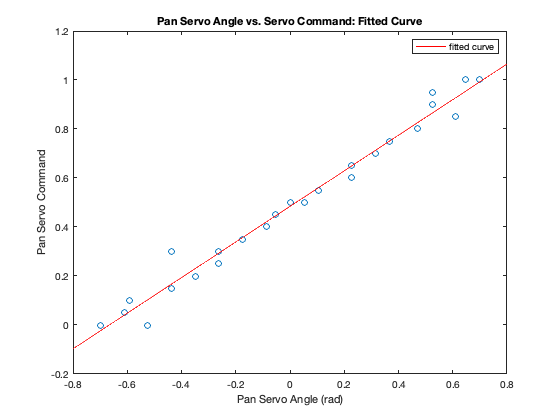

figure()
plot(panAngle_shifted,panPos,"o")
hold on;
plot(fit_pan)
xlabel('Pan Servo Angle (rad)')
ylabel('Pan Servo Command')
title('Pan Servo Angle vs. Servo Command: Fitted Curve')